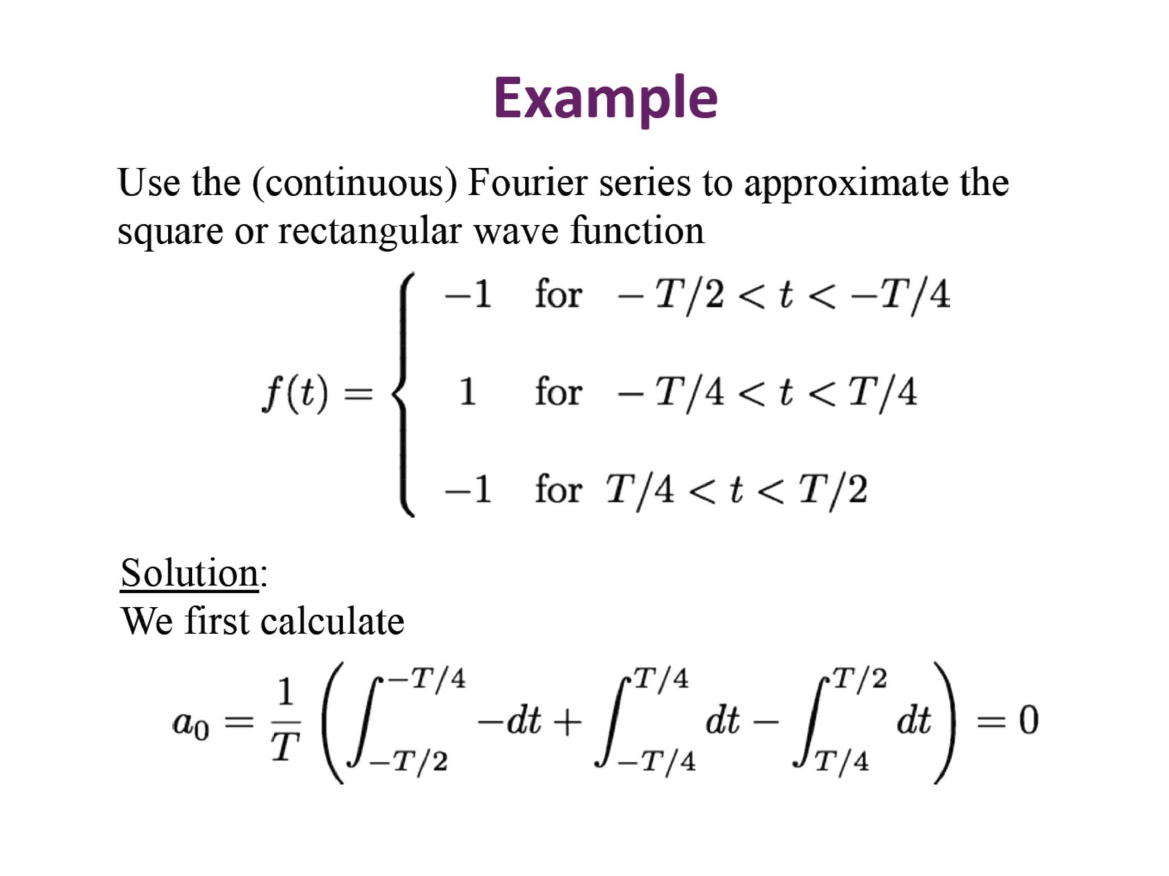

clear
clf
clc

Ts=0.01;
T=5;
syms t y

t=-T/2:Ts:T/2-Ts

t =    -2.5000   -2.4900   -2.4800   -2.4700   -2.4600   -2.4500   -2.4400   -2.4300   -2.4200   -2.4100   -2.4000   -2.3900   -2.3800   -2.3700   -2.3600   -2.3500   -2.3400   -2.3300   -2.3200   -2.3100   -2.3000   -2.2900   -2.2800   -2.2700   -2.2600   -2.2500   -2.2400   -2.2300   -2.2200   -2.2100   -2.2000   -2.1900   -2.1800   -2.1700   -2.1600   -2.1500   -2.1400   -2.1300   -2.1200   -2.1100   -2.1000   -2.0900   -2.0800   -2.0700   -2.0600   -2.0500   -2.0400   -2.0300   -2.0200   -2.0100



f((-T/2<t)&(t<-T/4))=-1;
f((-T/4<t)&(t<T/4))=1;
f((T/4<t)&(t<T/2))=-1

f =      0    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


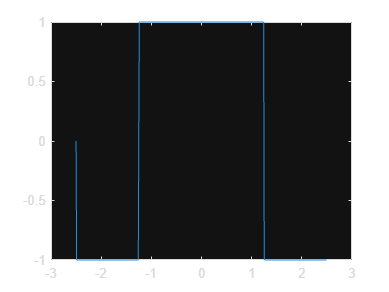

plot(t,f)


syms t y
N=7;
n=1:N;

a0=(2/T)*(int(-1,t,-T/2,-T/4)+int(1,t,-T/4,T/4)+int(-1,t,T/4,T/2))

$$a0 = 0$$

a_n=(2/T)*(int(-1*cos(2*pi*n*t/T),t,-T/2,-T/4)+int(1*cos(2*pi*n*t/T),t,-T/4,T/4)+int(-1*cos(2*pi*n*t/T),t,T/4,T/2))

$$a\_n = \left(\begin{array}{ccccccc} \frac{4}{\pi } & 0 & -\frac{4}{3\,\pi } & 0 & \frac{4}{5\,\pi } & 0 & -\frac{4}{7\,\pi } \end{array}\right)$$

b_n=(2/T)*(int(-1*sin(2*pi*n*t/T),t,-T/2,-T/4)+int(1*sin(2*pi*n*t/T),t,-T/4,T/4)+int(-1*sin(2*pi*n*t/T),t,T/4,T/2))

$$b\_n = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


F=a0/2;
for i=1:N
    F=F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
end
F

$$F = \frac{4\,\cos\left(2\,\pi \,t\right)}{5\,\pi }+\frac{4\,\cos\left(\frac{2\,\pi \,t}{5}\right)}{\pi }-\frac{4\,\cos\left(\frac{6\,\pi \,t}{5}\right)}{3\,\pi }-\frac{4\,\cos\left(\frac{14\,\pi \,t}{5}\right)}{7\,\pi }$$

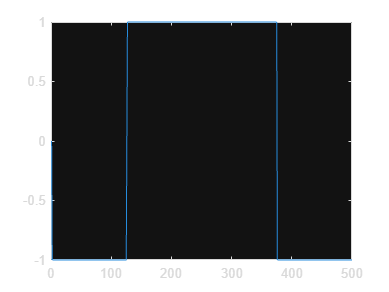

figure
hold off
plot(f)

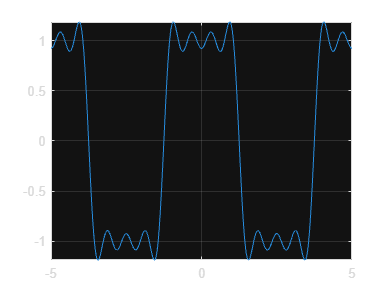

fplot(F)
hold off
grid on